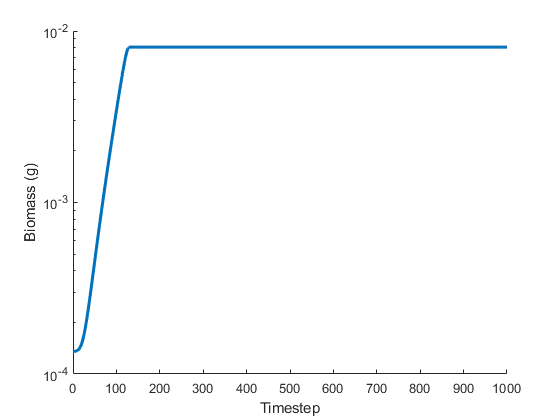

xmax = 1000;
rnum = 21;

figure();
plotBiomassTimecourse(mannosetable.bio{rnum},{'yeastGEMxml_noMaintRxn.txt'},'l');
xlim([0 xmax]);

%ylim([0.0001 0.01]);
figure();
plotmets = {'man-D[e]','glc-D[e]','cellulose','enzyme[e]'};
plotMediaTimecourse(mannosetable.media{rnum},plotmets,'l');

Dot indexing is not supported for variables of this type.

Error in plotMediaTimecourse (line 63)
x = unique(table.t);

xlim([0 xmax]);
ylim([1e-10,1e3]);

oleateplot = true;
%oleateplot = false;
if oleateplot
    figure();
    plotMediaTimecourse(mannosetable.media{rnum},{'oleate[e]','palmitoleate[e]'},true);
end

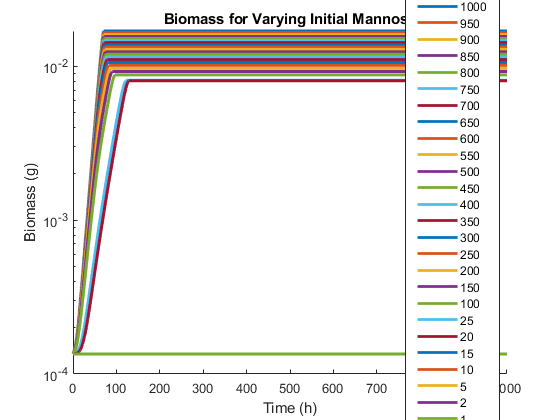


allbiomassplot = true;
%allbiomassplot = false;
if allbiomassplot
[nrow,ncol] = size(mannosetable);
figure();
hold on;
xlabel('Time (h)');
ylabel('Biomass (g)');
set(gca,'yscale','log');
    title('Biomass for Varying Initial Mannose')
for i = 1:nrow
    b = mannosetable.bio{i};
    plot(b.t,b.biomass,'displayname',num2str(mannosetable.scale(i)),'LineWidth',2);
end
leg = legend('location','best');
title(leg,'Mannose Scale');
hold off;
end